
%% generate path
%{.
dis = 0.5;
angle = 27;
deltaAngle = angle / 3;
scale = 0.65;

pathStartAll = zeros(4, 0);
pathAll = zeros(5, 0);
pathList = zeros(5, 0);
pathID = 0;
groupID = 0;

yawsAll = zeros(1,0);

weight = 0.5;
longth = 0.6;

figure;
hold on;
box on;
axis equal;
xlabel('X (m)');
ylabel('Y (m)');

fprintf('\nGenerating paths\n');


Generating paths



for shift1 = -angle : deltaAngle : angle
    wayptsStart = [0, 0, 0;
                   dis, shift1, 0];
    
    pathStartR = 0 : 0.01 : dis;
    pathStartShift = spline(wayptsStart(:, 1), wayptsStart(:, 2), pathStartR);
    
    pathStartX = pathStartR .* cos(pathStartShift * pi / 180);
    pathStartY = pathStartR .* sin(pathStartShift * pi / 180);
    pathStartZ = zeros(size(pathStartX));
    
    pathStart = [pathStartX; pathStartY; pathStartZ; ones(size(pathStartX)) * groupID];
    pathStartAll = [pathStartAll, pathStart];
    
    for shift2 = -angle * scale + shift1 : deltaAngle * scale : angle * scale + shift1
        for shift3 = -angle * scale^2 + shift2 : deltaAngle * scale^2 : angle * scale^2 + shift2
                waypts = [pathStartR', pathStartShift', pathStartZ';
                          2 * dis, shift2, 0;
                          3 * dis - 0.001, shift3, 0;
                          3 * dis, shift3, 0];

                pathR = 0 : 0.01 : waypts(end, 1);
                pathShift = spline(waypts(:, 1), waypts(:, 2), pathR);

                pathX = pathR .* cos(pathShift * pi / 180);
                pathY = pathR .* sin(pathShift * pi / 180);
                pathZ = zeros(size(pathX));
                yaws = zeros(size(pathX));
                for i = 1:size(pathX,2)-1
                    if i == 1
                        yaws(i)=0;
                    else
                        yaws(i)=atan((pathY(i+1)-pathY(i-1))/(pathX(i+1)-pathX(i-1)));
                    end  
                    
                end
                yaws(end)=shift3*pi/180;
                path = [pathX; pathY; pathZ; ones(size(pathX)) * pathID; ones(size(pathX)) * groupID];
                pathAll = [pathAll, path];
                pathList = [pathList, [pathX(end); pathY(end); pathZ(end); pathID; groupID]];
                yawsAll = [yawsAll,yaws];
                pathID = pathID + 1;

                plot3(pathX, pathY, pathZ);
        end
    end
    
    groupID = groupID + 1
end

groupID = 1

groupID = 2

groupID = 3

groupID = 4

groupID = 5

groupID = 6

groupID = 7



%}

%% find correspondence
%{.
voxelSize = 0.01;
searchRadius = 0.5;
offsetX = 1.6;
offsetY = 2;
voxelNumX = 161;
voxelNumY = 401;

fprintf('\nPreparing voxels\n');


Preparing voxels


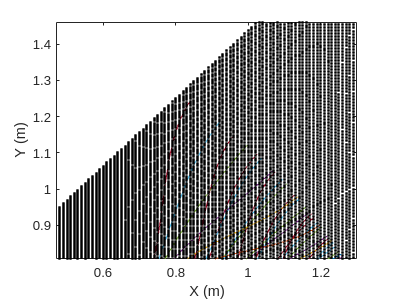


indPoint = 1;
voxelPointNum = voxelNumX * voxelNumY;
voxelPoints = zeros(voxelPointNum, 2);
for indX = 0 : voxelNumX - 1
    x = offsetX - voxelSize * indX;
    scaleY = x / offsetX + searchRadius / offsetY * (offsetX - x) / offsetX;
    for indY = 0 : voxelNumY - 1
        y = scaleY * (offsetY - voxelSize * indY);

        voxelPoints(indPoint, 1) = x;
        voxelPoints(indPoint, 2) = y;
        
        indPoint  = indPoint + 1;
    end
end

plot3(voxelPoints(:, 1), voxelPoints(:, 2), zeros(voxelPointNum, 1), 'k.');


fprintf('\nCollision checking\n');


Collision checking



[ind, dis] = rangesearch(pathAll(1 : 2, :)', voxelPoints, searchRadius);

corxs=zeros(1,0);
corys=zeros(1,0);
corzs=zeros(1,0);
for i = 1 : voxelPointNum
    
    indVoxel = sort(ind{i});
    indVoxelNum = size(indVoxel, 2);
    corx=voxelPoints(i,1);
    cory=voxelPoints(i,2);
    pathIndRec = -1;
    for j = 1 : indVoxelNum
        pathInd = pathAll(4, indVoxel(j));
        x = pathAll(1,indVoxel(j));
        y = pathAll(2,indVoxel(j));
        yaw = yawsAll(1,indVoxel(j));

        if pathInd == pathIndRec
            continue;
        end
        x2 = cos(yaw)*(corx-x)+sin(yaw)*(cory-y);
        y2 = -sin(yaw)*(corx-x)+cos(yaw)*(cory-y);
        if x2<-longth/2||x2>longth/2||y2<-weight/2||y2>weight/2
            continue;
        end
        pathIndRec = pathInd;
    end
    if pathIndRec ~= -1
        corxs=[corxs,corx];
        corys=[corys,cory];
        corzs=[corzs,0];
    end
    
    if mod(i, 1000) == 0
        i
    end
end

i = 1000

i = 2000

i = 3000

i = 4000

i = 5000

i = 6000

i = 7000

i = 8000

i = 9000

i = 10000

i = 11000

i = 12000

i = 13000

i = 14000

i = 15000

i = 16000

i = 17000

i = 18000

i = 19000

i = 20000

i = 21000

i = 22000

i = 23000

i = 24000

i = 25000

i = 26000

i = 27000

i = 28000

i = 29000

i = 30000

i = 31000

i = 32000

i = 33000

i = 34000

i = 35000

i = 36000

i = 37000

i = 38000

i = 39000

i = 40000

i = 41000

i = 42000

i = 43000

i = 44000

i = 45000

i = 46000

i = 47000

i = 48000

i = 49000

i = 50000

i = 51000

i = 52000

i = 53000

i = 54000

i = 55000

i = 56000

i = 57000

i = 58000

i = 59000

i = 60000

i = 61000

i = 62000

i = 63000

i = 64000

plot(corxs,corys)

